filename="meas5.wav";
SDR=audioread(filename);
info = audioinfo(filename)

info = struct with fields:
             Filename: 'C:\Users\Wout\OneDrive - Universiteit Antwerpen\Documenten\Master\1 MAP\Simulation\SNR\SNR\Exact FFT measurement of IQ Data\meas5.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 1000000
         TotalSamples: 136860000
             Duration: 136.8600
                Title: '137.55 MHz, BW 1 MHz, 2023-02-23 12:58'
              Comment: 'Created by DESKTOP-3EC4Q02\Wout on 2023-02-23 12:58:36, filename C:\Users\Wout\OneDrive - Universiteit Antwerpen\Bureaublad\23-Feb-2023 125836.937 137.550MHz.wav'
               Artist: 'SDR-Radio.com, B210 (A:A)'
        BitsPerSample: 32


The number of bins used in the fft is: 4096.000000 
 This results in the following resolution: 244.140625
The processing gain is 33.113300 dB


value = -125.9448

index = 3069

noisefloor = -145.1590

ENBW = 37.7028

noisefloor = -145.1590

SignaltoNoiseRatio = 19.2142

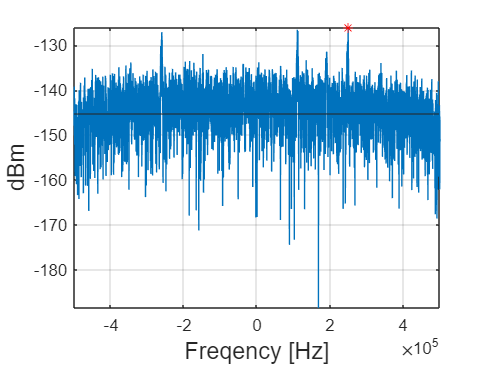

sampleRate= info.SampleRate;
center_freq=137.55; %in MHz
seconds=4;
SDR_snippet=SDR(((seconds-1)*1000000:seconds*1000000),:);

IQData = SDR(:,1)+1i*SDR(:,2);
%IQData=IQData.*hamming(length(IQData))
%plot_FFT_IQ(IQData,1,.01*sampleRate,sampleRate,137.8);
%spectrogram(IQData)
result=Corrected_FFT(IQData,1,0.1*sampleRate,sampleRate,center_freq);